# Legge di moto servomotori

Questo script simula fedelmente come la legge di moto viene calcolata sul microcontrollore.

clear all
close all
clf
target_angle = 70; %angolo di target da raggiungere
previous_angle = 30;
smoothing = 0.05; %parametro che regola quanto è morbida e quindi lenta la curva
resolution = 0.3; %Risoluzione angolare del servo. (0.3 gradi)
i = 1;
q = [30];
time = 5; %secondi, tempo di movimentazione

Prima Il programma esegue una simulazione della movimentazione e calcola quante iterazioni sono necessarie per la movimentazione.

while(target_angle-previous_angle >= resolution )
    previous_angle = smoothing*target_angle + (1-smoothing)*previous_angle;
    i = i+1;
end

Noto il numero di iterazioni è possibile calcolare il passo temporale tra passo e l'altro

timestamp = linspace(0,time,i);
target_angle = 70; %angolo di target da raggiungere
previous_angle = 30;
while(target_angle-previous_angle >= resolution )
    previous_angle = smoothing*target_angle + (1-smoothing)*previous_angle;
    q = [q previous_angle]; %Vettore che contiene la posizione del motore
end

In questo modo si ottiene una correlazione tra tempo di movimentazione e movimentazione.

Questa tecnica risulta vantaggiosa nel momento in cui si controllano più motori che devono compiere movimentazione diverse contemporaneamente. Si esegue lo stesso calcolo per ogni motore e si calcola il passo temporale per ogni motore in modo che tutti i motori terminino il movimento assieme.

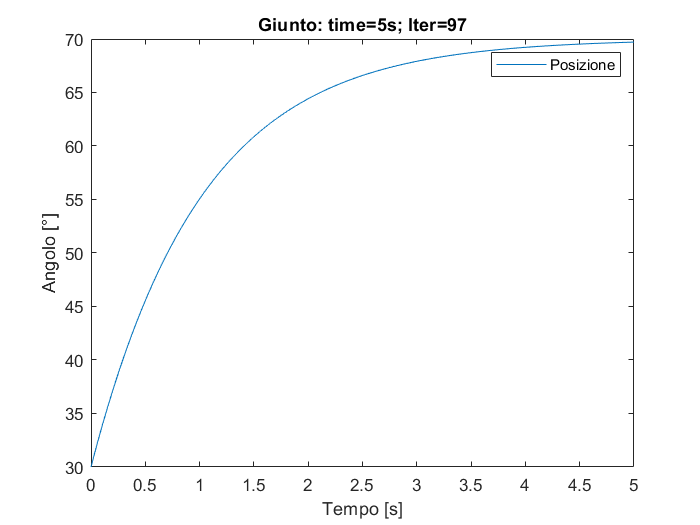

plot(timestamp,q);
title("Giunto: time=" + num2str(time) + "s; Iter="+num2str(i))
legend("Posizione")
xlabel("Tempo [s]")
ylabel("Angolo [°]")